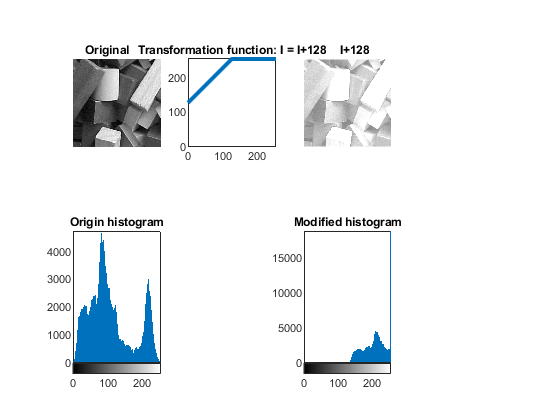

clearvars;
close all;
clc;
% read image files
I1 = imread('images/A0.tif');
I2 = imread('images/A1.tif');
I3 = imread('images/A2.tif');
I4 = imread('images/A3.tif');




% generate transformation function
x = 0:255;
y = x+128;
ind = find(y>255);
y(ind) = 255;

% apply transformation
I6 = imadd(I1,128); %add 128 to each pixel

subplot(2,4,1), imshow(I1), title('Original      ');
subplot(2,4,3), imshow(I6), title('    I+128');

subplot(2,4,5), imhist(I1), title('Origin histogram'), 
subplot(2,4,2), plot(x,y,'LineWidth', 3), axis([0 255 0 255]), title('Transformation function: I = I+128'), axis square;
subplot(2,4,7), imhist(I6), title('Modified histogram');

mean_img = mean(I1(:));
max_img = max(I1(:));
min_img = min(I1(:));
mean_img1 = mean(I6(:));
max_img1 = max(I6(:));
min_img1 = min(I6(:));
fprintf(' Original Max: %i\n Original min: %i\n Original mean: %i\n\n Modified Max: %i\n Modified min: %i\n Modified mean: %i ',max_img,min_img,mean_img,max_img1,min_img1,mean_img1);

 Original Max: 254
 Original min: 0
 Original mean: 1.087636e+02

 Modified Max: 255
 Modified min: 128
 Modified mean: 2.168558e+02 

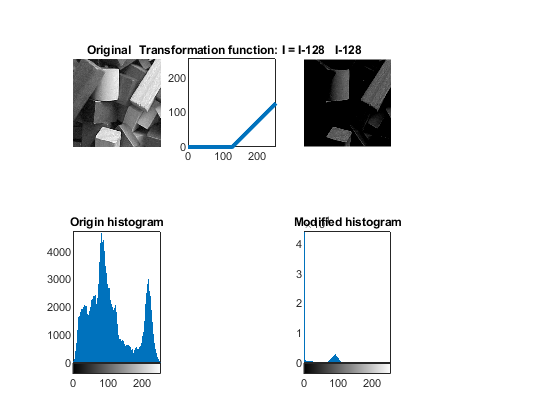


x = 0:255;
y = x-128;
ind = find(y<0);
y(ind) = 0;
I6 = imsubtract(I1,128); %subtract 128 from each pixel
subplot(2,4,1), imshow(I1), title('Original     ');subplot(2,4,3), imshow(I6), title('I-128');subplot(2,4,5), imhist(I1), title('Origin histogram'), subplot(2,4,2), plot(x,y,'LineWidth', 3), axis([0 255 0 255]), title('Transformation function: I = I-128'), axis square;,subplot(2,4,7), imhist(I6), title('Modified histogram');

mean_img = mean(I1(:));
max_img = max(I1(:));
min_img = min(I1(:));
mean_img1 = mean(I6(:));
max_img1 = max(I6(:));
min_img1 = min(I6(:));
fprintf(' Original Max: %i\n Original min: %i\n Original mean: %i\n\n Modified Max: %i\n Modified min: %i\n Modified mean: %i ',max_img,min_img,mean_img,max_img1,min_img1,mean_img1);

 Original Max: 254
 Original min: 0
 Original mean: 1.087636e+02

 Modified Max: 126
 Modified min: 0
 Modified mean: 1.961671e+01 

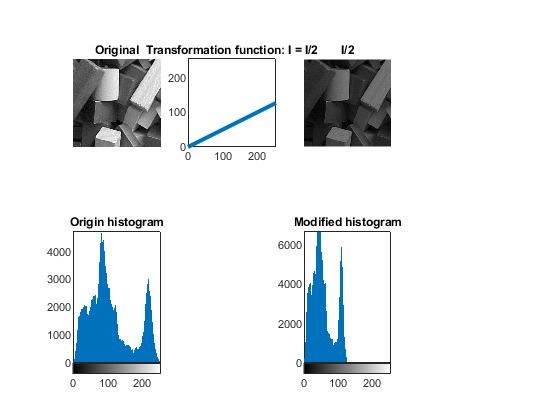


x = 0:255;
y = x/2;
I6 = imdivide(I1,2); %divide each pixel by 2
subplot(2,4,1), imshow(I1), title('Original');subplot(2,4,3), imshow(I6), title('I/2');subplot(2,4,5), imhist(I1), title('Origin histogram'), subplot(2,4,2), plot(x,y,'LineWidth', 3), axis([0 255 0 255]), title('Transformation function: I = I/2'), axis square;subplot(2,4,7), imhist(I6), title('Modified histogram');

mean_img = mean(I1(:));
max_img = max(I1(:));
min_img = min(I1(:));
mean_img1 = mean(I6(:));
max_img1 = max(I6(:));
min_img1 = min(I6(:));
fprintf(' Original Max: %i\n Original min: %i\n Original mean: %i\n\n Modified Max: %i\n Modified min: %i\n Modified mean: %i ',max_img,min_img,mean_img,max_img1,min_img1,mean_img1);

 Original Max: 254
 Original min: 0
 Original mean: 1.087636e+02

 Modified Max: 127
 Modified min: 0
 Modified mean: 5.463108e+01 

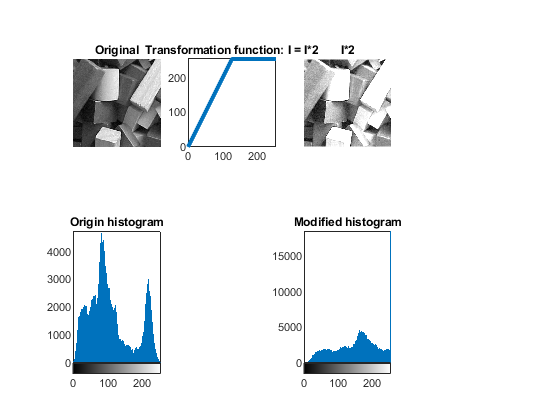


x = 0:255;
y = x*2;
ind = find(y>255);
y(ind) = 255;
I6 = immultiply(I1,2); 
subplot(2,4,1), imshow(I1), title('Original');subplot(2,4,3), imshow(I6), title('I*2');subplot(2,4,5), imhist(I1), title('Origin histogram'), subplot(2,4,2), plot(x,y,'LineWidth', 3), axis([0 255 0 255]), title('Transformation function: I = I*2'), axis square;,subplot(2,4,7), imhist(I6), title('Modified histogram');

mean_img = mean(I1(:));
max_img = max(I1(:));
min_img = min(I1(:));
mean_img1 = mean(I6(:));
max_img1 = max(I6(:));
min_img1 = min(I6(:));
fprintf(' Original Max: %i\n Original min: %i\n Original mean: %i\n\n Modified Max: %i\n Modified min: %i\n Modified mean: %i ',max_img,min_img,mean_img,max_img1,min_img1,mean_img1);

 Original Max: 254
 Original min: 0
 Original mean: 1.087636e+02

 Modified Max: 255
 Modified min: 0
 Modified mean: 1.780027e+02 

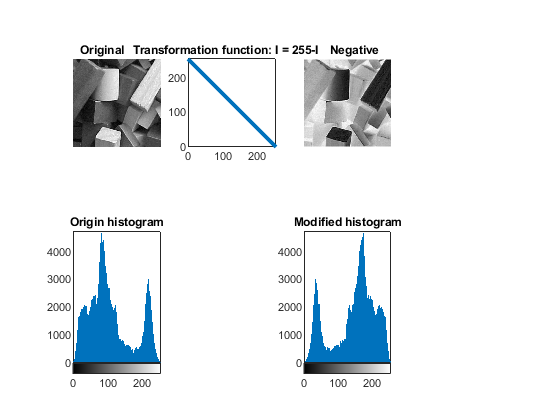


x = 0:255;
y = 255-x;
I6 = imcomplement(I1); 
subplot(2,4,1), imshow(I1), title('Original         ');subplot(2,4,3), imshow(I6), title('    Negative');subplot(2,4,5), imhist(I1), title('Origin histogram'), subplot(2,4,2), plot(x,y,'LineWidth', 3), axis([0 255 0 255]), title('Transformation function: I = 255-I    '), axis square;subplot(2,4,7), imhist(I6), title('Modified histogram');

mean_img = mean(I1(:));
max_img = max(I1(:));
min_img = min(I1(:));
mean_img1 = mean(I6(:));
max_img1 = max(I6(:));
min_img1 = min(I6(:));
fprintf(' Original Max: %i\n Original min: %i\n Original mean: %i\n\n Modified Max: %i\n Modified min: %i\n Modified mean: %i ',max_img,min_img,mean_img,max_img1,min_img1,mean_img1);

 Original Max: 254
 Original min: 0
 Original mean: 1.087636e+02

 Modified Max: 255
 Modified min: 1
 Modified mean: 1.462364e+02 

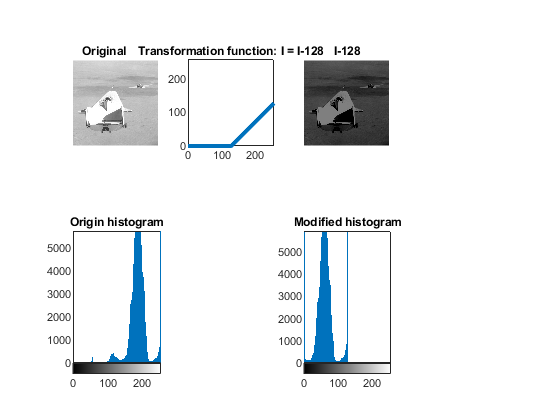


x = 0:255;
y = x-128;
ind = find(y<0);
y(ind) = 0;
I6 = imsubtract(I2,128); %subtract 128 from each pixel
subplot(2,4,1), imshow(I2), title('Original       ');subplot(2,4,3), imshow(I6), title('I-128');subplot(2,4,5), imhist(I2), title('Origin histogram'), subplot(2,4,2), plot(x,y,'LineWidth', 3), axis([0 255 0 255]), title('Transformation function: I = I-128'), axis square;,subplot(2,4,7), imhist(I6), title('Modified histogram');

mean_img = mean(I2(:));
max_img = max(I2(:));
min_img = min(I2(:));
mean_img1 = mean(I6(:));
max_img1 = max(I6(:));
min_img1 = min(I6(:));
fprintf(' Original Max: %i\n Original min: %i\n Original mean: %i\n\n Modified Max: %i\n Modified min: %i\n Modified mean: %i ',max_img,min_img,mean_img,max_img1,min_img1,mean_img1);

 Original Max: 255
 Original min: 50
 Original mean: 1.892563e+02

 Modified Max: 127
 Modified min: 0
 Modified mean: 6.217257e+01 

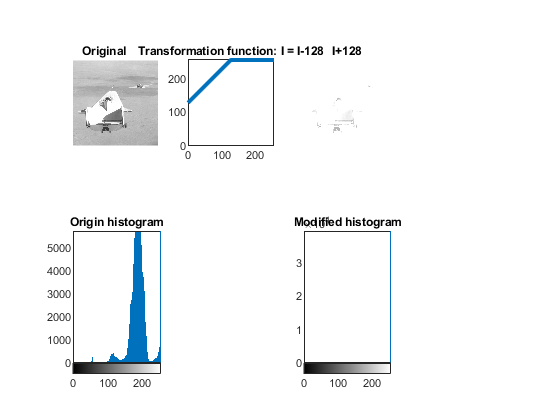


x = 0:255;
y = x+128;
ind = find(y>255);
y(ind) = 255;
I6 = imadd(I2,128); %add 128 to each pixel
subplot(2,4,1), imshow(I2), title('Original       ');subplot(2,4,3), imshow(I6), title('I+128');subplot(2,4,5), imhist(I2), title('Origin histogram'), subplot(2,4,2), plot(x,y,'LineWidth', 3), axis([0 255 0 255]), title('Transformation function: I = I-128'), axis square;,subplot(2,4,7), imhist(I6), title('Modified histogram');

mean_img = mean(I2(:));
max_img = max(I2(:));
min_img = min(I2(:));
mean_img1 = mean(I6(:));
max_img1 = max(I6(:));
min_img1 = min(I6(:));
fprintf(' Original Max: %i\n Original min: %i\n Original mean: %i\n\n Modified Max: %i\n Modified min: %i\n Modified mean: %i ',max_img,min_img,mean_img,max_img1,min_img1,mean_img1);

 Original Max: 255
 Original min: 50
 Original mean: 1.892563e+02

 Modified Max: 255
 Modified min: 178
 Modified mean: 2.541224e+02 

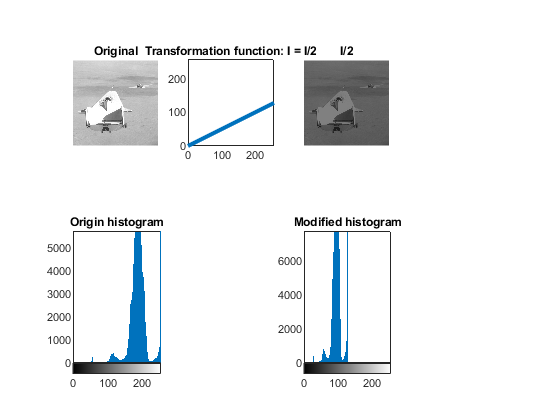

x = 0:255;
y = x/2;
I6 = imdivide(I2,2);
subplot(2,4,1), imshow(I2), title('Original');subplot(2,4,3), imshow(I6), title('I/2');subplot(2,4,5), imhist(I2), title('Origin histogram'), subplot(2,4,2), plot(x,y,'LineWidth', 3), axis([0 255 0 255]), title('Transformation function: I = I/2'), axis square;subplot(2,4,7), imhist(I6), title('Modified histogram');

mean_img = mean(I2(:));
max_img = max(I2(:));
min_img = min(I2(:));
mean_img1 = mean(I6(:));
max_img1 = max(I6(:));
min_img1 = min(I6(:));
fprintf(' Original Max: %i\n Original min: %i\n Original mean: %i\n\n Modified Max: %i\n Modified min: %i\n Modified mean: %i ',max_img,min_img,mean_img,max_img1,min_img1,mean_img1);

 Original Max: 255
 Original min: 50
 Original mean: 1.892563e+02

 Modified Max: 128
 Modified min: 25
 Modified mean: 9.489180e+01 

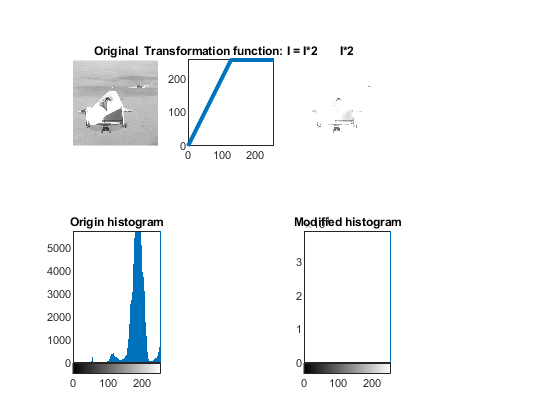

x = 0:255;
y = x*2;
ind = find(y>255);
y(ind) = 255;
I6 = immultiply(I2,2); 
subplot(2,4,1), imshow(I2), title('Original');subplot(2,4,3), imshow(I6), title('I*2');subplot(2,4,5), imhist(I2), title('Origin histogram'), subplot(2,4,2), plot(x,y,'LineWidth', 3), axis([0 255 0 255]), title('Transformation function: I = I*2'), axis square;,subplot(2,4,7), imhist(I6), title('Modified histogram');

mean_img = mean(I2(:));
max_img = max(I2(:));
min_img = min(I2(:));
mean_img1 = mean(I6(:));
max_img1 = max(I6(:));
min_img1 = min(I6(:));
fprintf(' Original Max: %i\n Original min: %i\n Original mean: %i\n\n Modified Max: %i\n Modified min: %i\n Modified mean: %i ',max_img,min_img,mean_img,max_img1,min_img1,mean_img1);

 Original Max: 255
 Original min: 50
 Original mean: 1.892563e+02

 Modified Max: 255
 Modified min: 100
 Modified mean: 2.532061e+02 

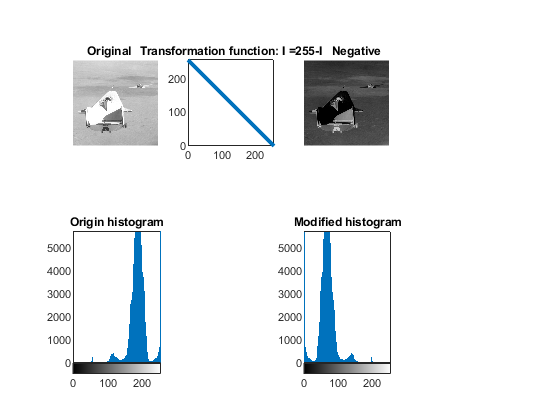

x = 0:255;
y = 255-x;
I6 = imcomplement(I2); 
subplot(2,4,1), imshow(I2), title('Original    ');subplot(2,4,3), imshow(I6), title('      Negative');subplot(2,4,5), imhist(I2), title('Origin histogram'), subplot(2,4,2), plot(x,y,'LineWidth', 3), axis([0 255 0 255]), title('Transformation function: I =255-I'), axis square;subplot(2,4,7), imhist(I6), title('Modified histogram');

mean_img = mean(I2(:));
max_img = max(I2(:));
min_img = min(I2(:));
mean_img1 = mean(I6(:));
max_img1 = max(I6(:));
min_img1 = min(I6(:));
fprintf(' Original Max: %i\n Original min: %i\n Original mean: %i\n\n Modified Max: %i\n Modified min: %i\n Modified mean: %i ',max_img,min_img,mean_img,max_img1,min_img1,mean_img1);

 Original Max: 255
 Original min: 50
 Original mean: 1.892563e+02

 Modified Max: 205
 Modified min: 0
 Modified mean: 6.574369e+01 

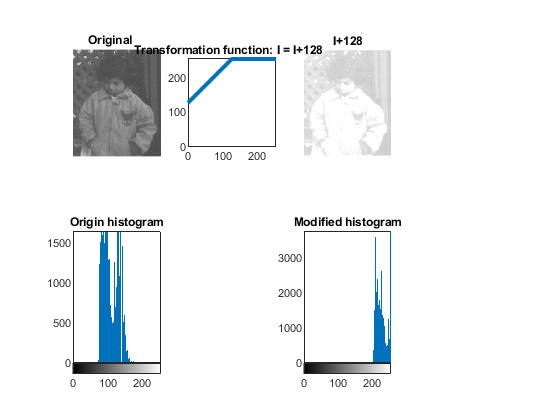

x = 0:255;
y = x+128;
ind = find(y>255);
y(ind) = 255;
I6 = imadd(I3,128); 
subplot(2,4,1), imshow(I3), title('Original    ');subplot(2,4,3), imshow(I6), title('I+128');subplot(2,4,5), imhist(I3), title('Origin histogram'), subplot(2,4,2), plot(x,y,'LineWidth', 3), axis([0 255 0 255]), title('Transformation function: I = I+128  '), axis square;,subplot(2,4,7), imhist(I6), title('Modified histogram');

mean_img = mean(I3(:));
max_img = max(I3(:));
min_img = min(I3(:));
mean_img1 = mean(I6(:));
max_img1 = max(I6(:));
min_img1 = min(I6(:));
fprintf(' Original Max: %i\n Original min: %i\n Original mean: %i\n\n Modified Max: %i\n Modified min: %i\n Modified mean: %i ',max_img,min_img,mean_img,max_img1,min_img1,mean_img1);

 Original Max: 224
 Original min: 74
 Original mean: 1.103037e+02

 Modified Max: 255
 Modified min: 202
 Modified mean: 2.346003e+02 

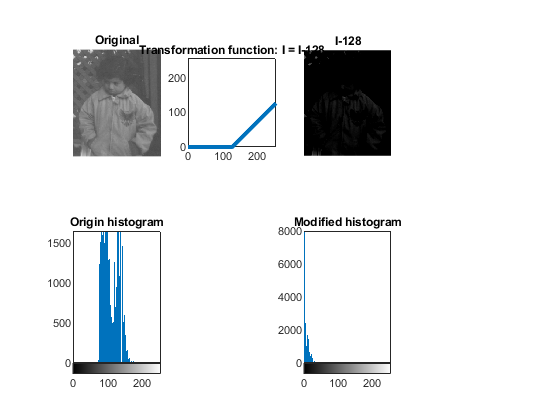

x = 0:255;
y = x-128;
ind = find(y<0);
y(ind) = 0;
I6 = imsubtract(I3,128); %subtract 128 from each pixel
subplot(2,4,1), imshow(I3), title('Original');subplot(2,4,3), imshow(I6), title('I-128');subplot(2,4,5), imhist(I3), title('Origin histogram'), subplot(2,4,2), plot(x,y,'LineWidth', 3), axis([0 255 0 255]), title('Transformation function: I = I-128'), axis square;,subplot(2,4,7), imhist(I6), title('Modified histogram');

mean_img = mean(I3(:));
max_img = max(I3(:));
min_img = min(I3(:));
mean_img1 = mean(I6(:));
max_img1 = max(I6(:));
min_img1 = min(I6(:));
fprintf(' Original Max: %i\n Original min: %i\n Original mean: %i\n\n Modified Max: %i\n Modified min: %i\n Modified mean: %i ',max_img,min_img,mean_img,max_img1,min_img1,mean_img1);

 Original Max: 224
 Original min: 74
 Original mean: 1.103037e+02

 Modified Max: 96
 Modified min: 0
 Modified mean: 3.395862e+00 

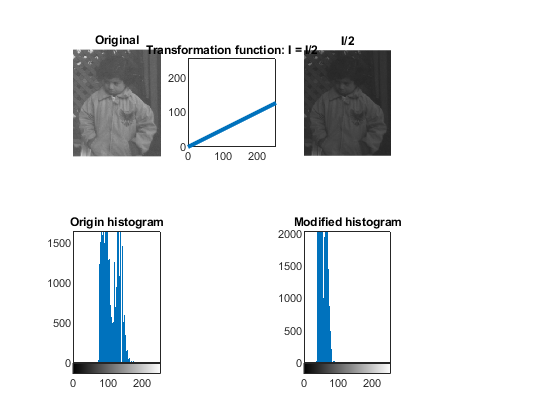

x = 0:255;
y = x/2;
I6 = imdivide(I3,2);
subplot(2,4,1), imshow(I3), title('Original');subplot(2,4,3), imshow(I6), title('I/2');subplot(2,4,5), imhist(I3), title('Origin histogram'), subplot(2,4,2), plot(x,y,'LineWidth', 3), axis([0 255 0 255]), title('Transformation function: I = I/2'), axis square;subplot(2,4,7), imhist(I6), title('Modified histogram');

mean_img = mean(I3(:));
max_img = max(I3(:));
min_img = min(I3(:));
mean_img1 = mean(I6(:));
max_img1 = max(I6(:));
min_img1 = min(I6(:));
fprintf(' Original Max: %i\n Original min: %i\n Original mean: %i\n\n Modified Max: %i\n Modified min: %i\n Modified mean: %i ',max_img,min_img,mean_img,max_img1,min_img1,mean_img1);

 Original Max: 224
 Original min: 74
 Original mean: 1.103037e+02

 Modified Max: 112
 Modified min: 37
 Modified mean: 5.541047e+01 

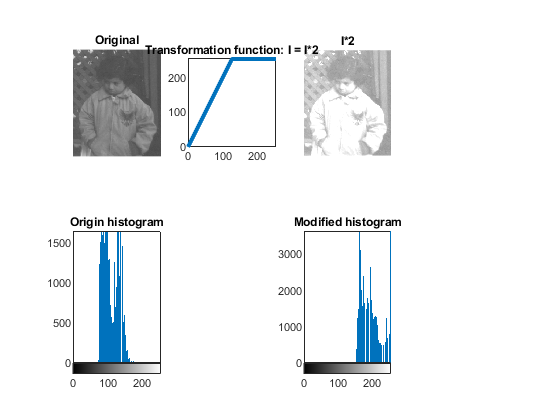

x = 0:255;
y = x*2;
ind = find(y>255);
y(ind) = 255;
I6 = immultiply(I3,2); 
subplot(2,4,1), imshow(I3), title('Original');subplot(2,4,3), imshow(I6), title('I*2');subplot(2,4,5), imhist(I3), title('Origin histogram'), subplot(2,4,2), plot(x,y,'LineWidth', 3), axis([0 255 0 255]), title('Transformation function: I = I*2'), axis square;,subplot(2,4,7), imhist(I6), title('Modified histogram');

mean_img = mean(I3(:));
max_img = max(I3(:));
min_img = min(I3(:));
mean_img1 = mean(I6(:));
max_img1 = max(I6(:));
min_img1 = min(I6(:));
fprintf(' Original Max: %i\n Original min: %i\n Original mean: %i\n\n Modified Max: %i\n Modified min: %i\n Modified mean: %i ',max_img,min_img,mean_img,max_img1,min_img1,mean_img1);

 Original Max: 224
 Original min: 74
 Original mean: 1.103037e+02

 Modified Max: 255
 Modified min: 148
 Modified mean: 2.135081e+02 

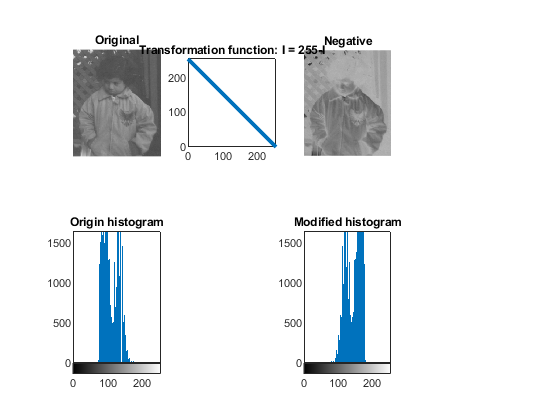

x = 0:255;
y = 255-x;
I6 = imcomplement(I3); 
subplot(2,4,1), imshow(I3), title('Original');subplot(2,4,3), imshow(I6), title('Negative');subplot(2,4,5), imhist(I3), title('Origin histogram'), subplot(2,4,2), plot(x,y,'LineWidth', 3), axis([0 255 0 255]), title('Transformation function: I = 255-I'), axis square;subplot(2,4,7), imhist(I6), title('Modified histogram');

mean_img = mean(I3(:));
max_img = max(I3(:));
min_img = min(I3(:));
mean_img1 = mean(I6(:));
max_img1 = max(I6(:));
min_img1 = min(I6(:));
fprintf(' Original Max: %i\n Original min: %i\n Original mean: %i\n\n Modified Max: %i\n Modified min: %i\n Modified mean: %i ',max_img,min_img,mean_img,max_img1,min_img1,mean_img1);

 Original Max: 224
 Original min: 74
 Original mean: 1.103037e+02

 Modified Max: 181
 Modified min: 31
 Modified mean: 1.446963e+02 

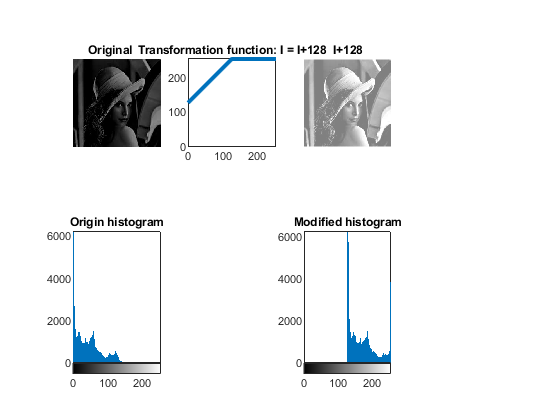

x = 0:255;
y = x+128;
ind = find(y>255);
y(ind) = 255;
I6 = imadd(I4,128); 
subplot(2,4,1), imshow(I4), title('Original    ');subplot(2,4,3), imshow(I6), title('I+128');subplot(2,4,5), imhist(I4), title('Origin histogram'), subplot(2,4,2), plot(x,y,'LineWidth', 3), axis([0 255 0 255]), title('Transformation function: I = I+128'), axis square;subplot(2,4,7), imhist(I6), title('Modified histogram');

mean_img = mean(I4(:));
max_img = max(I4(:));
min_img = min(I4(:));
mean_img1 = mean(I6(:));
max_img1 = max(I6(:));
min_img1 = min(I6(:));
fprintf(' Original Max: %i\n Original min: %i\n Original mean: %i\n\n Modified Max: %i\n Modified min: %i\n Modified mean: %i ',max_img,min_img,mean_img,max_img1,min_img1,mean_img1);

 Original Max: 161
 Original min: 0
 Original mean: 3.509021e+01

 Modified Max: 255
 Modified min: 128
 Modified mean: 1.629235e+02 

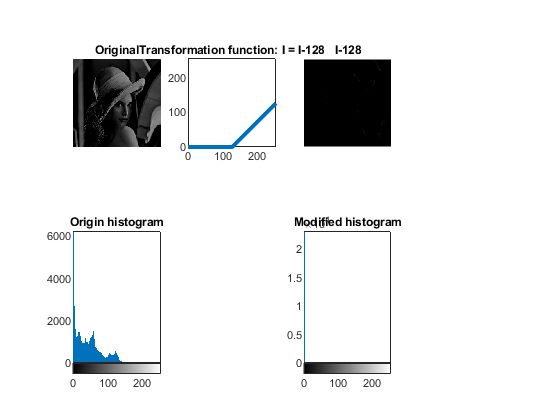

x = 0:255;
y = x-128;
ind = find(y<0);
y(ind) = 0;
I6 = imsubtract(I4,128); %subtract 128 from each pixel
subplot(2,4,1), imshow(I4), title('Original');subplot(2,4,3), imshow(I6), title('I-128');subplot(2,4,5), imhist(I4), title('Origin histogram'); subplot(2,4,2), plot(x,y,'LineWidth', 3), axis([0 255 0 255]), title('Transformation function: I = I-128'), axis square;subplot(2,4,7), imhist(I6), title('Modified histogram');

mean_img = mean(I4(:));
max_img = max(I4(:));
min_img = min(I4(:));
mean_img1 = mean(I6(:));
max_img1 = max(I6(:));
min_img1 = min(I6(:));
fprintf(' Original Max: %i\n Original min: %i\n Original mean: %i\n\n Modified Max: %i\n Modified min: %i\n Modified mean: %i ',max_img,min_img,mean_img,max_img1,min_img1,mean_img1);

 Original Max: 161
 Original min: 0
 Original mean: 3.509021e+01

 Modified Max: 33
 Modified min: 0
 Modified mean: 1.440790e-01 

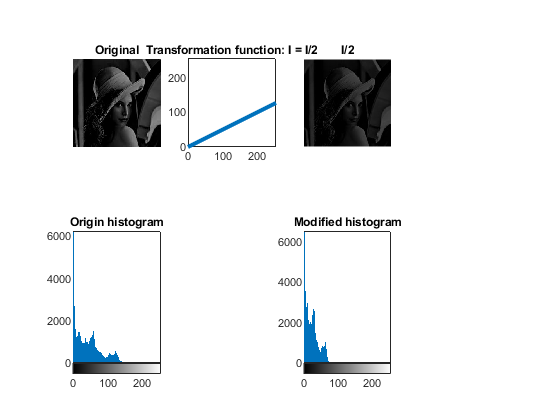

x = 0:255;
y = x/2;
I6 = imdivide(I4,2);
subplot(2,4,1), imshow(I4), title('Original');subplot(2,4,3), imshow(I6), title('I/2');subplot(2,4,5), imhist(I4), title('Origin histogram'), subplot(2,4,2), plot(x,y,'LineWidth', 3), axis([0 255 0 255]), title('Transformation function: I = I/2'), axis square;subplot(2,4,7), imhist(I6), title('Modified histogram');

mean_img = mean(I4(:));
max_img = max(I4(:));
min_img = min(I4(:));
mean_img1 = mean(I6(:));
max_img1 = max(I6(:));
min_img1 = min(I6(:));
fprintf(' Original Max: %i\n Original min: %i\n Original mean: %i\n\n Modified Max: %i\n Modified min: %i\n Modified mean: %i ',max_img,min_img,mean_img,max_img1,min_img1,mean_img1);

 Original Max: 161
 Original min: 0
 Original mean: 3.509021e+01

 Modified Max: 81
 Modified min: 0
 Modified mean: 1.774031e+01 

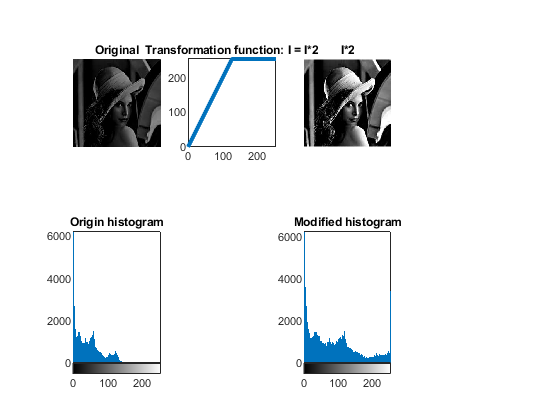

x = 0:255;
y = x*2;
ind = find(y>255);
y(ind) = 255;
I6 = immultiply(I4,2); 
subplot(2,4,1), imshow(I4), title('Original');subplot(2,4,3), imshow(I6), title('I*2');subplot(2,4,5), imhist(I4), title('Origin histogram'), subplot(2,4,2), plot(x,y,'LineWidth', 3), axis([0 255 0 255]), title('Transformation function: I = I*2'), axis square;subplot(2,4,7), imhist(I6), title('Modified histogram');

mean_img = mean(I4(:));
max_img = max(I4(:));
min_img = min(I4(:));
mean_img1 = mean(I6(:));
max_img1 = max(I6(:));
min_img1 = min(I6(:));
fprintf(' Original Max: %i\n Original min: %i\n Original mean: %i\n\n Modified Max: %i\n Modified min: %i\n Modified mean: %i ',max_img,min_img,mean_img,max_img1,min_img1,mean_img1);

 Original Max: 161
 Original min: 0
 Original mean: 3.509021e+01

 Modified Max: 255
 Modified min: 0
 Modified mean: 6.986963e+01 

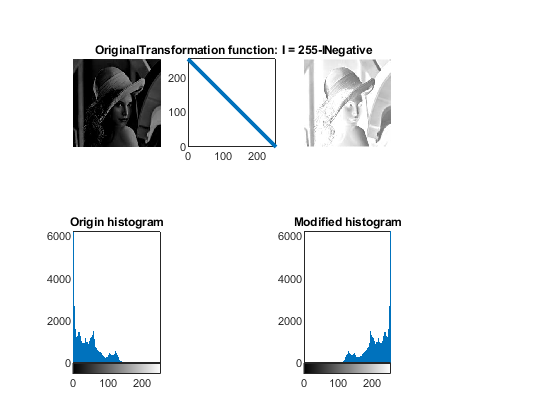

x = 0:255;
y = 255-x;
I6 = imcomplement(I4); 
subplot(2,4,1), imshow(I4), title('Original');subplot(2,4,3), imshow(I6), title('Negative');subplot(2,4,5), imhist(I4), title('Origin histogram'), subplot(2,4,2), plot(x,y,'LineWidth', 3), axis([0 255 0 255]), title('Transformation function: I = 255-I'), axis square;subplot(2,4,7), imhist(I6), title('Modified histogram');

mean_img = mean(I4(:));
max_img = max(I4(:));
min_img = min(I4(:));
mean_img1 = mean(I6(:));
max_img1 = max(I6(:));
min_img1 = min(I6(:));
fprintf(' Original Max: %i\n Original min: %i\n Original mean: %i\n\n Modified Max: %i\n Modified min: %i\n Modified mean: %i ',max_img,min_img,mean_img,max_img1,min_img1,mean_img1);

 Original Max: 161
 Original min: 0
 Original mean: 3.509021e+01

 Modified Max: 255
 Modified min: 94
 Modified mean: 2.199098e+02 